
data_wd = readtable('C:\Users\Alonso\Desktop\REGBOT\Ex_6\log_6_wd.txt');
data_wd = fillmissing(data_wd, 'nearest');

[t_wd,u_L_wd,u_R_wd,v_L_wd,v_R_wd,T_s_wd] = get_data(data_wd);

idwd = find(u_L_wd >= 4,1,'first');
idwd = idwd + 42;
idd_L_wd = iddata(v_L_wd(idwd:end),u_L_wd(idwd:end),T_s_wd);
G_L_wd = tfest(idd_L_wd,2,0) 

G_L_wd =
 
  From input "u1" to output "y1":
          12.1
  ---------------------
  s^2 + 12.67 s + 42.81
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                              
Estimated using TFEST on time domain data "idd_L_wd".
Fit to estimation data: 41.45%                       
FPE: 0.001048, MSE: 0.001043                         


[num, denom] = tfdata(G_L_wd); 
Kp = 5;
num = cell2mat(num)

num =          0         0   12.0975


denom = cell2mat(denom)

denom =     1.0000   12.6687   42.8059


simout = sim('C:\Users\Alonso\Desktop\REGBOT\Ex_8\simulink_model', 5); % simulate  for 5 seconds
plot(simout);

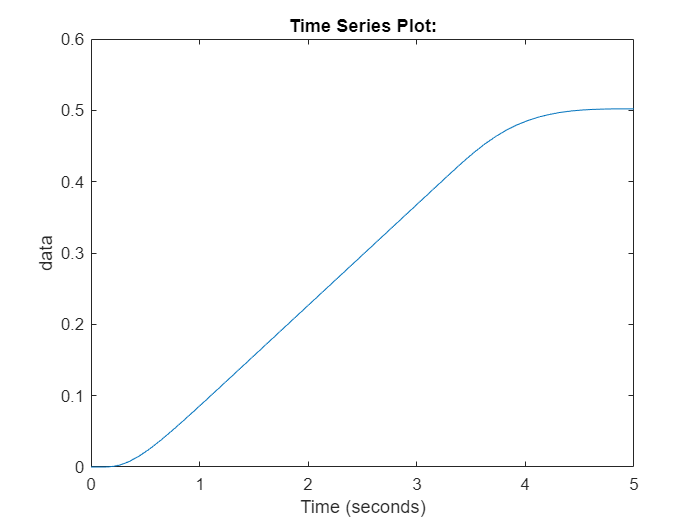

regbot_sim = sim("C:\Users\Alonso\Desktop\REGBOT\Ex_8\simulink_model", 5); % model_name is what you use for your own simulink model
plot(regbot_sim.simout);

bode()

function [t,u_L,u_R,v_L,v_R,T_s] = get_data(data)
    t = table2array(data(:,1));     % time stamps
    u_L = table2array(data(:,2));   % left motor voltage
    u_R = table2array(data(:,3));   % right motor voltage
    v_L = table2array(data(:,4));  % left motor velocity 
    v_R = table2array(data(:,5));  % right motor velocity
    T_s = t(2) - t(1);              % compute sampling time
end

